clear all
clc

load('../../../data/dynamic-2s-4s.mat')
rng(2022)

raw_tb = full_table

raw_tb = 261465×6 timetable
      Time          sEMG         MAV         RMS       Cue    Mean Frequency    Median Frequency
    _________    __________    ________    ________    ___    ______________    ________________

    0 sec              -2.5    0.021359    0.024076     0           0                  0        
    0.001 sec     -0.029297    0.021359    0.024076     0           0                  0        
    0.002 sec     -0.043945    0.021359    0.024077     0           0                  0        
    0.003 sec     -0.029297     0.02136    0.024077     0           0                  0        
    0.004 sec     -0.039062     0.02136    0.024078     0         

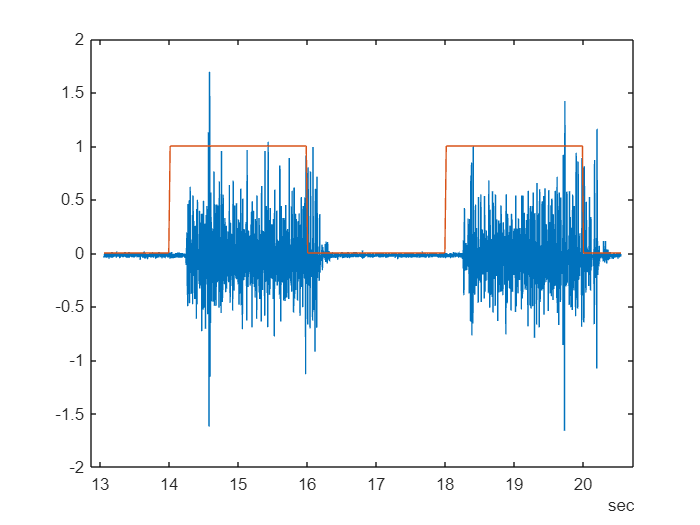

PLOT_DURATION = 7.5;
raw_fig = figure();
idx_start = randi(height(raw_tb), 1);
idx_end = idx_start + fs*PLOT_DURATION;
fig_tb = raw_tb(idx_start:idx_end, :);

xvals = fig_tb.Time;
plot(xvals, fig_tb.sEMG)
hold on
plot(xvals, fig_tb.Cue)
hold off

WINDOW_LEN_SEC = 0.1;
window_len_sam = fs*WINDOW_LEN_SEC

window_len_sam = 100

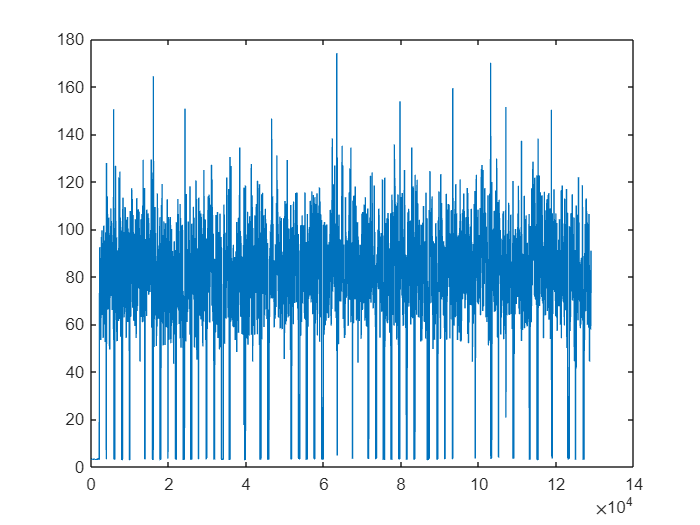

mdf = NaN(height(raw_tb),1);
j = 1;
for i=1:height(raw_tb)
    if i > window_len_sam && raw_tb.Cue(i)==1
        window_tb = raw_tb(i-window_len_sam:i, "sEMG");
        raw_sEMG = window_tb.sEMG;
        mdf(j) = medfreq(raw_sEMG, fs);
        j=j+1;
    end
end

plot(mdf)

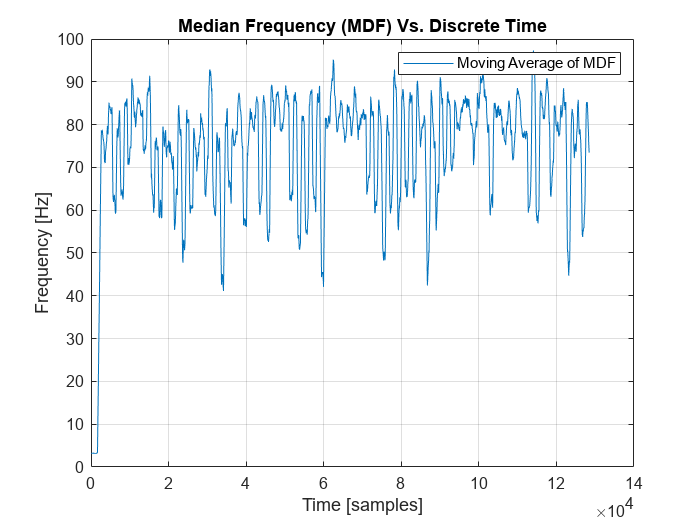

plot(movmean(mdf, 1000))
yline(mean(movmean(mdf, 1000)))
grid on
legend("Moving Average of MDF")
title("Median Frequency (MDF) Vs. Discrete Time")
xlabel("Time [samples]")
ylabel("Frequency [Hz]")

time_signal = full_table.sEMG;
signalAnalyzer(time_signal, 'SampleRate', fs)

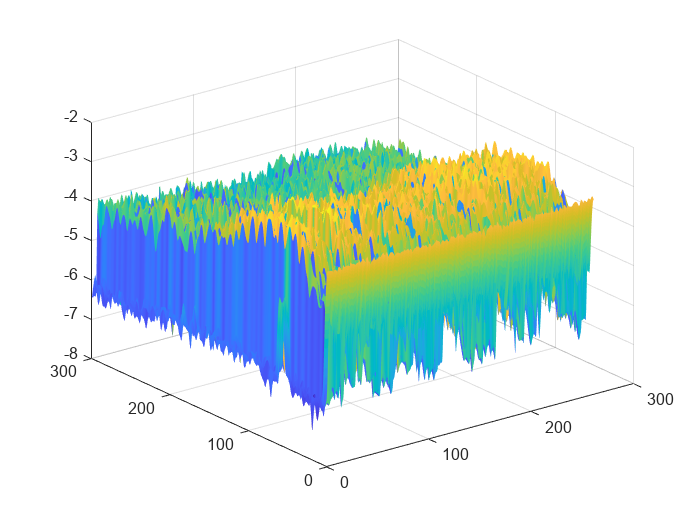

% Parameters
timeLimits = [0 261.464]; % seconds
frequencyLimits = [0 300]; % Hz
overlapPercent = 50;

%%
% Index into signal time region of interest
time_signal_ROI = time_signal(:);
sampleRate = 1000; % Hz
startTime = 0; % seconds
timeValues = startTime + (0:length(time_signal_ROI)-1).'/sampleRate;
minIdx = timeValues >= timeLimits(1);
maxIdx = timeValues <= timeLimits(2);
time_signal_ROI = time_signal_ROI(minIdx&maxIdx);
timeValues = timeValues(minIdx&maxIdx);

% Compute spectral estimate
% Run the function call below without output arguments to plot the results
[P,F,T] = pspectrum(time_signal_ROI,timeValues, ...
    'spectrogram', ...
    'FrequencyLimits',frequencyLimits, ...
    'OverlapPercent',overlapPercent);

surf(T, F, log10(P)), shading flat